# **PRACTICE 3. GRADIENT/NEWTON'S METHOD**

## Grado en Ingeniería Informática - Reconocimiento de Patrones

## Fernando M. Quintana Velázquez - Guillermo Bárcena González

# **EXERCISE 1: GRADIENT DESCENT**

**Given the function **$\mathbf{f}{\left(\mathbf{x},\mathbf{y}\right)}=\sin {\left(\frac{1}{2}{\mathbf{x}}^2 -\frac{1}{4}{\mathbf{y}}^2 +3\right)}\textrm{*cos}{\left(2\mathbf{x}+1+{\mathbf{e}}^{\mathbf{y}} \right)}$** determine the minimum of the function and the minimum direction in the point [0.5, 0].**

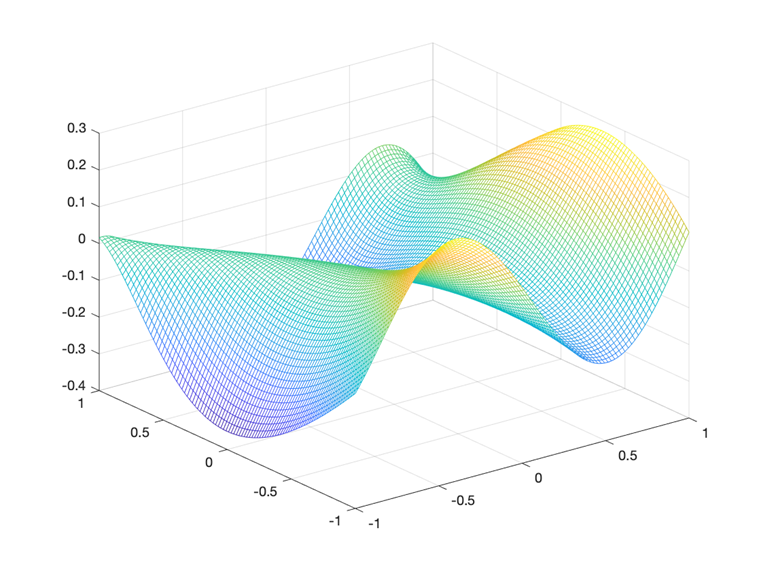

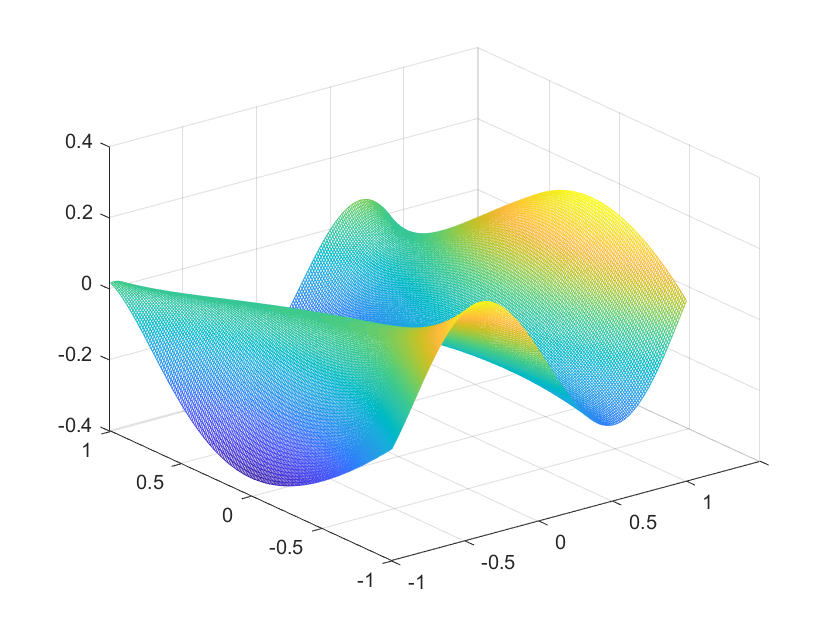

X=-1:0.01:1;
Y=-1:0.01:1;
[X,Y]=meshgrid(X,Y);
A=sin(((X.^2)/2)-((Y.^2)./4)+3).*cos(2*X+1+exp(Y));
mesh(A); xticklabels([-1,-0.5,0,0.5,1]); yticklabels([-1,-0.5,0,0.5,1])

**a) Use 0.1 as size step. How many iterations have been done? **

syms x y;
f = sin(((x.^2)/2)-((y.^2)./4)+3).*cos(2*x+1+exp(y));
f_dx = diff(f,x);
f_dy = diff(f,y);
sol = [0.5;0]; %starting at point [0.5/0]
for i=1:1000
   x_coord=sol(1,i);
   y_coord=sol(2,i);
   dx = subs(f_dx,{x,y},{x_coord,y_coord});
   dy = subs(f_dy,{x,y},{x_coord,y_coord});
   sol(:,i+1) = sol(:,i) - 0.1 * [dx;dy];
%    if isequal(sol(:,i),sol(:,i+1))
%        break;
%    end
   if abs(sol(:,i)-sol(:,i+1)) < 0.0001
       break;
   end
end
Text = sprintf('Number of runs: %d',i);
disp(Text)

Number of runs: 139


It takes 139 iterations to get to a difference smaller than 0.0001

**b) Change the size step at 0.01. How many iterations have been done now?**

syms x y;
f = sin(((x.^2)/2)-((y.^2)./4)+3).*cos(2*x+1+exp(y));
f_dx = diff(f,x);
f_dy = diff(f,y);
sol = [0.5;0]; %starting at point [0.5/0]
for i=1:1500
   x_coord=sol(1,i);
   y_coord=sol(2,i);
   dx = subs(f_dx,{x,y},{x_coord,y_coord});
   dy = subs(f_dy,{x,y},{x_coord,y_coord});
   sol(:,i+1) = sol(:,i) - 0.01 * [dx;dy];
%    if isequal(sol(:,i),sol(:,i+1))
%        break;
%    end
   if abs(sol(:,i)-sol(:,i+1)) < 0.0001
       break;
   end
end
Text = sprintf('Number of runs: %d',i);
disp(Text)

Number of runs: 1018


Now it takes 1018 itarations to get to a point where the result changes by less than 0.0001

**c) if you change the size step at 1, what happens?**

syms x y;
f = sin(((x.^2)/2)-((y.^2)./4)+3).*cos(2*x+1+exp(y));
f_dx = diff(f,x);
f_dy = diff(f,y);
sol = [0.5;0]; %starting at point [0.5/0]
for i=1:1500
   x_coord=sol(1,i);
   y_coord=sol(2,i);
   dx = subs(f_dx,{x,y},{x_coord,y_coord});
   dy = subs(f_dy,{x,y},{x_coord,y_coord});
   sol(:,i+1) = sol(:,i) - 1 * [dx;dy];
%    if isequal(sol(:,i),sol(:,i+1))
%        break;
%    end
   if abs(sol(:,i)-sol(:,i+1)) < 0.0001
       break;
   end
end
Text = sprintf('Number of runs: %d',i);
disp(Text)

Number of runs: 1500


Now the algorithm doesnt converge to a point inside our barrier of 1500 iterations

**d) Can you think any way to determine the size step that minimizes the number of iterations??**

One way would be by trail and error (Start with 0.001 and and try different learning rates to seewhich one performs best) or we could do a own gradient descent for the learning rate 

# **EXERCISE 2: NEWTON’S METHOD**

**a) Use the Newton algorithm to determine the minimum of the function **$\mathbf{f}{\left(\mathbf{x},\mathbf{y}\right)}=100{\left({\mathbf{x}}^2 -{\mathbf{y}}^2 \right)}+{\left(1+\mathbf{x}\right)}^2$** taking the point (10, 10) as initial value.**

syms x y;
f = 100*((x.^2)-(y.^2))+(1+x.^2);
f_dx = diff(f,x);
f_dy = diff(f,y);
%second differentiation
f_dxx = diff(f_dx,x);
f_dxy = diff(f_dx,y);
f_dyx = diff(f_dy,x);
f_dyy = diff(f_dy,y);
sol = [10;10]; %starting at point [10/10]
for i=1:1000
   x_coord=sol(1,i);
   y_coord=sol(2,i);
   dx = subs(f_dx,{x,y},{x_coord,y_coord});
   dy = subs(f_dy,{x,y},{x_coord,y_coord});       
   dxx = subs(f_dxx,{x,y},{x_coord,y_coord});       
   dxy = subs(f_dxy,{x,y},{x_coord,y_coord});
   dyx = subs(f_dyx,{x,y},{x_coord,y_coord});                     
   dyy = subs(f_dyy,{x,y},{x_coord,y_coord});       
   H = [dxx dxy;dyx dyy];                     
   sol(:,i+1) = sol(:,i) - 0.1 * inv(H)  * ([dx;dy]);   
   if abs(sol(:,i)-sol(:,i+1)) < 0.0001
       break;
   end
end
Text = sprintf('Number of runs: %d',i);
disp(Text)

Number of runs: 89
